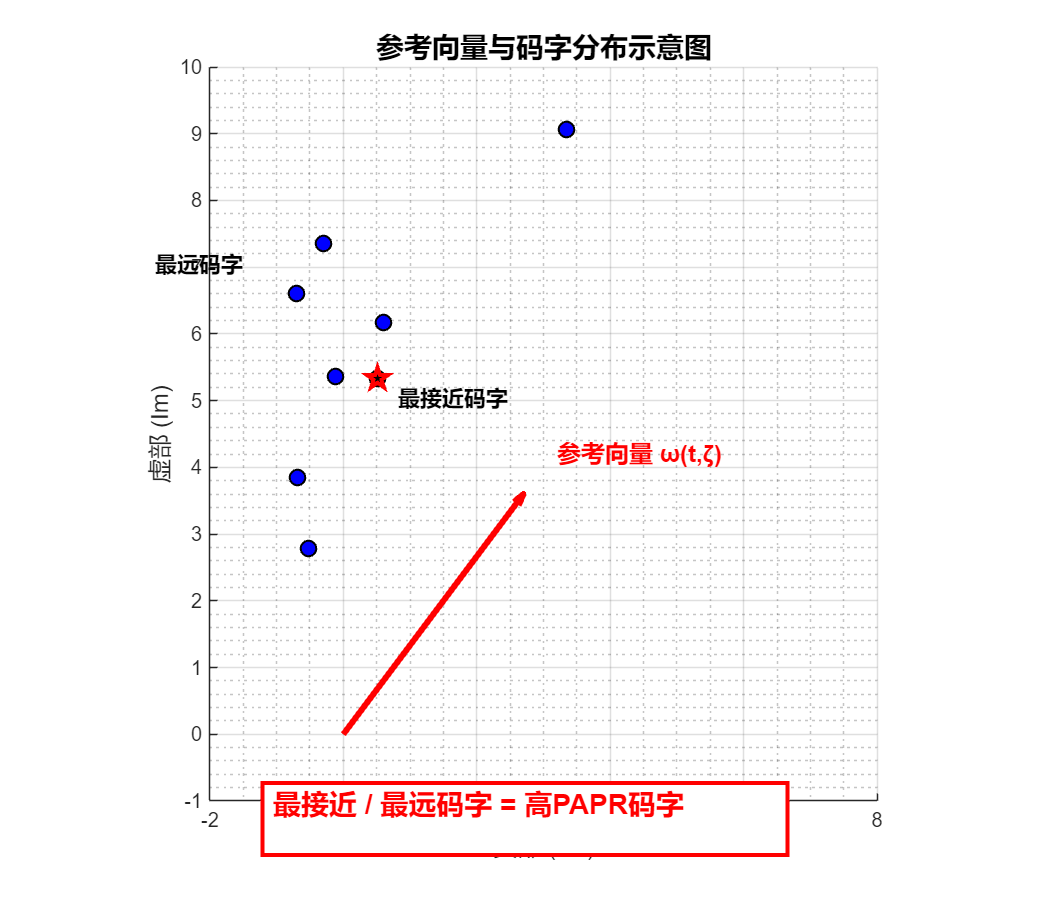

% 参考向量ω(t,ζ)与码字分布示意图（论文创新1核心逻辑，修正维度兼容问题）
clear; clc; close all;

%% 1. 核心参数设置（2维空间可视化，便于理解）
omega = [3, 4];  % 参考向量ω(t,ζ)（2维坐标，幅值适中便于观察）
N_codes = 10;    % 生成10个码字（数量适中，避免图形拥挤）
rng(1);          % 固定随机种子，保证结果可复现
% 修正：均值向量改为2行1列，与randn(2,N_codes)逐行广播（第1行均值1，第2行均值5）
codes = randn(2, N_codes) * 2 + [1; 5];  % 码字随机分布（方差2，维度完全匹配）

%% 2. 计算各码字与参考向量的欧氏距离（核心指标）
distances = sqrt(sum((codes - omega(:, ones(1, N_codes))).^2, 1));
[min_dist, min_idx] = min(distances);  % 最接近码字的索引
[max_dist, max_idx] = max(distances);  % 最远码字的索引

%% 3. 绘图设置（适配PPT，突出核心关系）
figure('Position', [100, 100, 700, 600]);  % 画布大小（宽×高）
set(gcf, 'Color', 'white');  % 白色背景，适配PPT

% 绘制所有码字（蓝色圆点，普通码字）
scatter(codes(1, :), codes(2, :), 60, 'b', 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 1);
hold on;

% 绘制参考向量ω（红色箭头，突出显示）
quiver(0, 0, omega(1), omega(2), 'Color', 'red', 'LineWidth', 3, 'MaxHeadSize', 0.15);
text(omega(1)+0.2, omega(2)+0.2, '参考向量 ω(t,ζ)', 'Color', 'red', 'FontSize', 12, 'FontWeight', 'bold');

% 标注最接近码字（黑色五角星，突出）
scatter(codes(1, min_idx), codes(2, min_idx), 120, 'k', 'pentagram', 'filled', 'MarkerEdgeColor', 'red', 'LineWidth', 2);
text(codes(1, min_idx)+0.3, codes(2, min_idx)-0.3, '最接近码字', 'Color', 'black', 'FontSize', 11, 'FontWeight', 'bold');

% 标注最远码字（黑色五角星，突出）
scatter(codes(1, max_idx), codes(2, max_idx), 120, 'k', 'pentagram', 'filled', 'MarkerEdgeColor', 'red', 'LineWidth', 2);
text(codes(1, max_idx)-0.8, codes(2, max_idx)+0.3, '最远码字', 'Color', 'black', 'FontSize', 11, 'FontWeight', 'bold');

% 核心结论标注（红色框+文字，强化记忆）
annotation('textbox', [0.25, 0.05, 0.5, 0.08], ...
           'String', '最接近 / 最远码字 = 高PAPR码字', ...
           'FontSize', 14, 'FontWeight', 'bold', 'Color', 'red', ...
           'BackgroundColor', 'white', 'EdgeColor', 'red', 'LineWidth', 2);

%% 4. 图形美化与坐标设置
xlabel('实部 (Re)', 'FontSize', 12);
ylabel('虚部 (Im)', 'FontSize', 12);
title('参考向量与码字分布示意图', 'FontSize', 14, 'FontWeight', 'bold');
grid on; grid minor;  % 网格辅助观察
axis equal;  % 等比例坐标，保证距离计算可视化准确
xlim([-2, 8]); ylim([-1, 10]);  % 固定坐标范围，避免码字溢出


% 平滑线条与图例（可选，增强可读性）
legend('普通码字', '参考向量ω(t,ζ)', '高PAPR码字（最接近/最远）', ...
       'Location', 'upper right', 'FontSize', 10);

错误使用 legend (第 263 行)
设置类 'Legend' 的属性 'Location' 时出错:
'upper right' 是无效值。请使用以下某个值: 'north' | 'south' | 'east' | 'west' | 'northeast' | 'northwest' | 'southeast' | 'southwest' | 'northoutside' | 'southoutside' | 'eastoutside' | 'westoutside' | 'northeastoutside' | 'northwestoutside' | 'southeastoutside' | 'southwestoutside' | 'best' | 'bestoutside' | 'none' | 'layout'。

set(findall(gcf, 'Type', 'Line'), 'LineSmoothing', 'on');